clc
clear all
b = 120; %in
c = 48;
S = c*b;
q =         [5.0 10.0 15.0 20.0 25.0 30.0 35.0 40.0 45.0 50.0]

q =      5    10    15    20    25    30    35    40    45    50


Cl_rigid =  [0.1487 0.1487 0.1487 0.1487 0.1487 0.1487 0.1487 0.1487 0.1487 0.1487]

Cl_rigid =     0.1487    0.1487    0.1487    0.1487    0.1487    0.1487    0.1487    0.1487    0.1487    0.1487


Cl_flex =   [0.1723 0.1746 0.1753 0.1742 0.1714 0.1670 0.1613 0.1546 0.1474 0.1400]

Cl_flex =     0.1723    0.1746    0.1753    0.1742    0.1714    0.1670    0.1613    0.1546    0.1474    0.1400


r = (q.*S.*Cl_flex)./(q.*S.*Cl_rigid)

r =     1.1587    1.1742    1.1789    1.1715    1.1527    1.1231    1.0847    1.0397    0.9913    0.9415


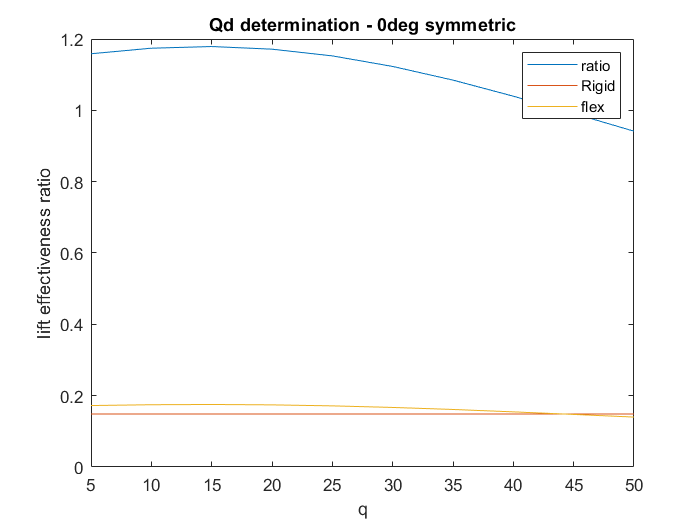

figure(1)
plot(q,r,'DisplayName','ratio')
hold on
plot(q,Cl_rigid,"DisplayName",'Rigid')
plot(q,Cl_flex,"DisplayName",'flex')
legend
title('Qd determination - 0deg symmetric')
xlabel('q')
ylabel('lift effectiveness ratio')
hold off

% yline(0,'DisplayName','x-intercept') 
% xline(13.75,'DisplayName','Qd = 13.75')